load('Itagui.mat');

ydata = Itagui(1:40)';

D = length(ydata);

Domain = [0 D-1];
xdata = 0 : D-1;

**Create the model as a table for GSUA-CSB toolbox implementation**

First, define the model as a symbolic structure

syms  Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t) Hit(t)
syms lambda beta_m mu_m theta_m mu_h beta_h theta_h...
    gamma_h

H = Hs + He + Hi + Hr;
M = Ms + Me + Mi;

ode1 = diff(Ms) == lambda - beta_m * Hi * Ms/H - mu_m * Ms;
ode2 = diff(Me) == beta_m * Hi * Ms/H - (theta_m + mu_m) * Me;
ode3 = diff(Mi) == theta_m * Me - mu_m * Mi;
ode4 = diff(Hs) == - beta_h * Mi * Hs/M + (He + Hi + Hr) * mu_h;
ode5 = diff(He) == beta_h * Mi * Hs/M - (theta_h + mu_h) * He;
ode6 = diff(Hi) == theta_h * He - (gamma_h + mu_h) * Hi;
ode7 = diff(Hr) == gamma_h * Hi - mu_h * Hr;
ode8 = diff(Hit) == theta_h * He;

odes = [ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8];
vars = [Hit Hi Me Hr Hs He Ms Mi];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [17 17             %Hit0
          17 17             %Hi    
          0	100             %Me
          0 100             %Hr
          50000	250000      %Hs
          0	1000            %He
          0	120000          %Ms
          0	100             %Mi
         ];
     
Range2 = [0	4
          0	4
          0.4	1.8
          0	42694
          0.0004 0.0004
          0.01 0.6
          0.7	1.75
          0.58	0.88
        ];     

Range = [Range1; Range2];

ParNames = {'\lambda'; '\beta_m'; '\mu_m'; '\theta_m'; '\beta_h'; '\theta_h'; '\gamma_h'};
VarNames = {'M_e(0)'; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)'};

FullNames = [VarNames; ParNames];

Finally, use the gsua_dpmat to create the functional table

[T,~] = gsua_dpmat(odes,vars,[0 39],'Model','output',2,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Row = ["M_e(0)"; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)';...
         '\beta_h';'\beta_m'; '\gamma_h';'\Lambda'; '\mu_m'; '\theta_h'; '\theta_m'];

Define the nominal curve as the best factor estimation

load('Results/Estimations/Deepest_Itagui.mat')
T.Nominal = Deep;

**Perform the once-at-time (OAT) algorithm before CSB estimation**

T_oat = gsua_oatr2(T,'lim',0.2,'parallel',false,'correct',false);

Expansion-reduction Method OAT is being launched
------------------------------------
Calculus of \theta_m Starting
Range for \theta_m Done!
Initial range of \theta_m(13)--> 0.58        0.88
Actual range --> 0.50483      1.6041
Calculus of \theta_h Starting
Range for \theta_h Done!
Initial range of \theta_h(12)--> 0.7        1.75
Actual range --> 0.601704       13.039
Calculus of \mu_m Starting
Range for \mu_m Done!
Initial range of \mu_m(11)--> 0.01         0.6
Actual range --> 0.48092     0.54212
Calculus of \Lambda Starting
Range for \Lambda Done!
Initial range of \Lambda(10)--> 0  42694
Actual range --> 2.6825      8.5474
Calculus of \gamma_h Starting
Range for \gamma_h Done!
Initial range of \gamma_h(9)--> 0.4         1.8
Actual range --> 0.36714     0.44457
Calculus of \beta_m Starting
Range for \beta_m Done!
Initial range of \beta_m(8)--> 0  4
Actual range --> 0.093707     0.11971
Calculus of \beta_h Starting
Range for \beta_h Done!
Initial range of \beta_h(7)--> 0  4
Actual ran

T_oat

T_oat = 13×2 table
                         Range               Nominal  
                ________________________    __________

    M_e(0)               0     0.0022574     0.0010033
    H_r(0)               0        12.368         5.497
    H_s(0)      1.1931e+05    2.1308e+05    1.6638e+05
    H_e(0)               0        43.533        19.348
    M_s(0)           53449    1.3069e+05         77445
    M_i(0)          4.9483         8.867        6.9006
    \beta_h         0.8764        1.0424       0.96559
    \beta_m       0.093707       0.11971       0.10775
    \gamma_h       0.36714       0.44457       0.40014
    \Lambda         2.6825        8.5474        4.5586
    \mu_m          0.48092       0.54212       0.50748
    

NRange=T_oat.Range;
NRange2=T.Range;
load Results\CSB\CSBRangeProtected_skewness_N_140.mat
deviationsL = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5

deviationsL =     0.2347
    0.2168
    0.1876
    0.2064
    0.0430
    0.1987
    0.1878
    0.2074
    0.1610
    0.0959


deviationsL2 = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5

deviationsU =     0.2439
    0.2564
    0.2178
    0.1910
    0.1667
    0.2022
    0.1917
    0.1853
    0.2122
    0.1769


deviationsU2 = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2)

meanL =     0.2523
    0.2473
    0.2064
    0.2753
    0.2864
    0.2115
    0.2281
    0.2518
    0.2441
    0.2552


meanL2 =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU =  mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2)

meanU =     0.7372
    0.7293
    0.6773
    0.7539
    0.6345
    0.7089
    0.6802
    0.6940
    0.6794
    0.5914


meanU2 =  mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);

load Results\CSB\CSBRangeProtected_skewness_N_500.mat
deviationsL(:,2) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,2) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,2) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,2) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
deviationsL2(:,2) = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU2(:,2) = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL2(:,2) =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU2(:,2) = mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_1000.mat
deviationsL(:,3) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,3) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,3) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,3) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
deviationsL2(:,3) = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU2(:,3) = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL2(:,3) =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU2(:,3) = mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_2000.mat
deviationsL(:,4) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,4) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,4) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,4) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
deviationsL2(:,4) = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU2(:,4) = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL2(:,4) =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU2(:,4) = mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_5000.mat
deviationsL(:,5) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,5) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,5) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,5) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
deviationsL2(:,5) = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU2(:,5) = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL2(:,5) =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU2(:,5) = mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);

1-mean((deviationsL+deviationsU))

ans =     0.6404    0.6804    0.7464    0.8379    0.8870


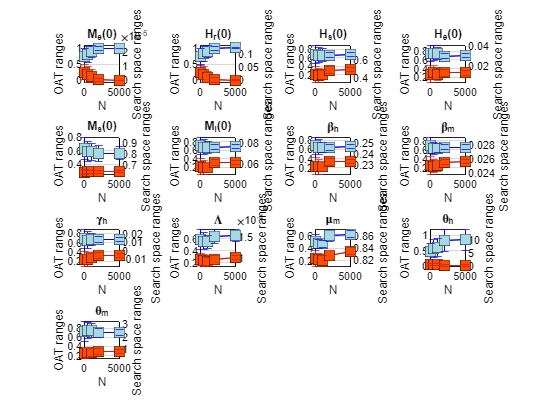

figure(1)
clf
for i=1:13
    subplot(4,4,i)
    colororder({'black','black'})
    yyaxis left
    errorbar([140,500,1000,2000,5000],meanU(i,:),deviationsU(i,:),"-s","MarkerSize",10,...
        "MarkerEdgeColor","black","MarkerFaceColor",[0.65 0.85 0.90],"Color","b")
    hold on
    errorbar([140,500,1000,2000,5000],meanL(i,:),deviationsL(i,:),"-s","MarkerSize",10,...
        "MarkerEdgeColor","black","MarkerFaceColor",[1 0.3 0],"Color",[0.8 0.1 0.1])
     ylim([min(meanL(i,:)-deviationsL(i,:)),max(meanU(i,:)+deviationsU(i,:))])
     xlim([0 5100])
     ylabel('OAT ranges')
     grid on
    yyaxis right
    ylim([min(meanL2(i,:)-deviationsL2(i,:)),max(meanU2(i,:)+deviationsU2(i,:))])
    ylabel('Search space ranges')
    title(T.Properties.RowNames{i})
    xlabel('N')
end

load Results\CSB\CSBRangeUnProtected_skewness_N_140.mat
deviationsL(:,1) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,1) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,1) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,1) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
deviationsL2(:,1) = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU2(:,1) = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL2(:,1) =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU2(:,1) = mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_500.mat
deviationsL(:,2) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,2) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,2) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,2) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
deviationsL2(:,2) = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU2(:,2) = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL2(:,2) =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU2(:,2) = mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_1000.mat
deviationsL(:,3) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,3) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,3) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,3) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
deviationsL2(:,3) = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU2(:,3) = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL2(:,3) =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU2(:,3) = mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_2000.mat
deviationsL(:,4) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,4) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,4) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,4) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
deviationsL2(:,4) = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU2(:,4) = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL2(:,4) =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU2(:,4) = mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
load Results\CSB\CSBRangeProtected_skewness_N_5000.mat
deviationsL(:,5) = std((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
deviationsU(:,5) = std((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),[],2)./0.5;
meanL(:,5) =  mean((Low-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
meanU(:,5) = mean((Up-NRange(:,1))./(NRange(:,2)-NRange(:,1)),2);
deviationsL2(:,5) = std((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
deviationsU2(:,5) = std((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),[],2)./0.5;
meanL2(:,5) =  mean((Low-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);
meanU2(:,5) = mean((Up-NRange2(:,1))./(NRange2(:,2)-NRange2(:,1)),2);

1-mean((deviationsL+deviationsU))

ans =     0.5768    0.6804    0.7464    0.8379    0.8870


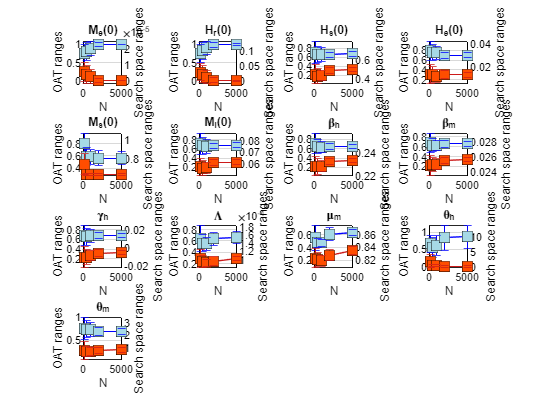

figure(2)
clf
for i=1:13
    subplot(4,4,i)
    colororder({'black','black'})
    yyaxis left
    errorbar([140,500,1000,2000,5000],meanU(i,:),deviationsU(i,:),"-s","MarkerSize",10,...
        "MarkerEdgeColor","black","MarkerFaceColor",[0.65 0.85 0.90],"Color","b")
    hold on
    errorbar([140,500,1000,2000,5000],meanL(i,:),deviationsL(i,:),"-s","MarkerSize",10,...
        "MarkerEdgeColor","black","MarkerFaceColor",[1 0.3 0],"Color",[0.8 0.1 0.1])
     ylim([min(meanL(i,:)-deviationsL(i,:)),max(meanU(i,:)+deviationsU(i,:))])
     xlim([0 5100])
     ylabel('OAT ranges')
     grid on
    yyaxis right
    ylim([min(meanL2(i,:)-deviationsL2(i,:)),max(meanU2(i,:)+deviationsU2(i,:))])
    ylabel('Search space ranges')
    title(T.Properties.RowNames{i})
    xlabel('N')
end

obj=@(pars) (gsua_deval(pars,T,xdata)-ydata)/std(ydata);
%[x,resnorm,residual,exitflag,output,lambda,jacobian] = lsqcurvefit(@(pars,xaxis) gsua_deval(pars,T,xaxis),T.Nominal',xdata,ydata,T.Range(:,1),T.Range(:,2));
[x,resnorm,residual,exitflag,output,lambda,jacobian] = lsqnonlin(obj,T.Nominal',T.Range(:,1),T.Range(:,2));


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


ci = nlparci(x,residual,'jacobian',jacobian)

ci = 1.0e+10 *

   -0.0000    0.0000
   -0.0033    0.0033
   -0.0387    0.0387
   -0.0000    0.0000
   -9.6818    9.6818
   -0.0009    0.0009
   -0.0000    0.0000
   -0.0000    0.0000
   -0.0000    0.0000
   -0.0006    0.0006


t2=table(x(:));
t2.Nominal=T.Nominal;
t2.Ci=ci;
t2.Properties.RowNames=T.Properties.RowNames

t2 = 13×3 table
                   Var1        Nominal                  Ci            
                __________    __________    __________________________

    M_e(0)       0.0010033     0.0010033        -1249.8         1249.8
    H_r(0)          5.4969         5.497    -3.3067e+07     3.3067e+07
    H_s(0)      1.6638e+05    1.6638e+05    -3.8709e+08     3.8742e+08
    H_e(0)          19.348        19.348        -756.89         795.59
    M_s(0)           77447         77445    -9.6818e+10     9.6818e+10
    M_i(0)          6.9008        6.9006     -8.599e+06      8.599e+06
    \beta_h        0.96557       0.96559        -7494.9         7496.8
    \beta_m        0.10775       0.10775        -835.38         835.59
    \gamma_h      

%T_ia=gsua_ia(T,EstimatedParams(1:1e3,:)',true,false,true);